clc;clear;close all;

## 1、生成点

% warning off
% 
% x = [-0.17263699	0.64102824	0.619187272	-0.169604585	-0.172290695	0.640753956	0.621242344	-0.170769907	-0.171522965	0.640246152	0.624506602	-0.171830944	-0.17083717	0.639008371	0.628110178	-0.171314854];
% y = [0.018979904	0.142571117	0.609214188	0.276047528	-0.053249894	-0.032656584	0.438329502	0.208959385	-0.125595109	-0.206542736	0.267949915	0.140160375	-0.198118165	-0.378594402	0.096932468	0.069163785];
% z = [-0.344388792	-0.670489171	0.286631526	0.1830114	-0.309268295	-0.580626074	0.372157833	0.220360057	-0.273244453	-0.491250982	0.458562455	0.258402244	-0.237311062	-0.402116506	0.545590665	0.294559421];
% 
% 
% azimuth = 5.819341;
% elevation = 1.582673;
% 
% P1 = [-0.25222006 0.655135248 -0.327650295];
% P2 = [-0.249753513 -0.390018781 0.195244076];
% 
% % xx = [-0.166541824	-0.143183482	0.086083038	0.156469149	0.466618822	0.56448817	0.839716947	0.807804096];
% % yy = [-0.049231542	0.233661612	-0.104236007	0.34170614	-0.091332629	0.380144412	0.261440943	0.017627278];
% % zz = [0.365326614	-0.524532874	0.659289339	-0.829545167	0.707237057	-0.813472591	-0.522760129	0.428110448];
% % PointFC = [xx;yy;zz];
% Points = [x;y;z];
% % Points = [Points,PointFC];
% 
% PAB = Points(:,5);

tic

## 1、读取点

warning off
[num,txt,raw] = xlsread("2024_12_21.xlsx");
num(4:5,:)=[];
x = num(23,~isnan(num(23,:)));
y = num(25,~isnan(num(25,:)));
z = num(24,~isnan(num(24,:)));
azimuth = num(20,1);
elevation = num(20,2);
Points = [x;y;z];

PAB = Points(:,5);
% P1 = num(1,[3,4,2]);
% P2 = num(2,[3,4,2]);


P1 = [ 0.341, -0.355, -0.253];
P2 = [-0.509, 0.580, -0.257];

## 2、拟合圆柱

[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Points,P1,P2);
toc

历时 51.220448 秒。


## 3、A、B面点测试

numShengLu = 5;
phi = pi/4;

toff = zeros(1,2*numShengLu);
roff = zeros(1,2*numShengLu);

Ang = -ShengLuJiaoJiSuan(numShengLu);

[PointTable_A_off,PointTable_B_off,BianHao] = Calculat_A_and_B_Points_after_Offest2(Bottom_round_center1',Bottom_round_center2',MTaon',Mcenter',Mradial,PAB,phi,Ang,toff,roff);
PointTable_A_offP = PointTable_A_off';
PointTable_B_offP = PointTable_B_off';

## 4、绘图验证

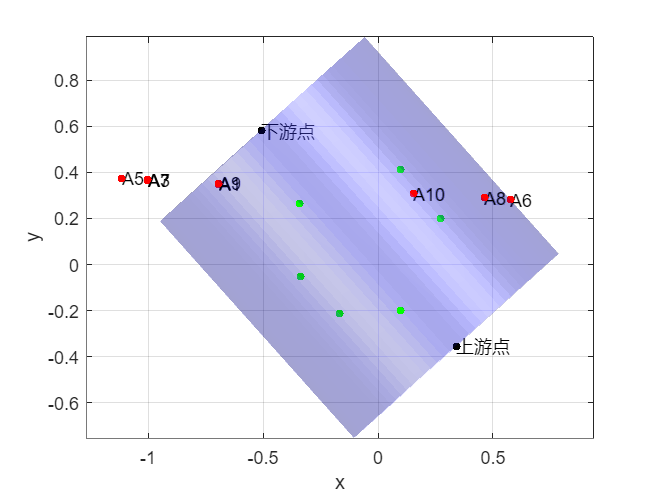

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
scatter3(PointTable_A_offP(1,1),PointTable_A_offP(1,2),PointTable_A_offP(1,3),20,'filled','red')
text(PointTable_A_offP(1,1),PointTable_A_offP(1,2),PointTable_A_offP(1,3),['A',num2str(BianHao(1,1))])

scatter3(PointTable_A_offP(2,1),PointTable_A_offP(2,2),PointTable_A_offP(2,3),20,'filled','red')
text(PointTable_A_offP(2,1),PointTable_A_offP(2,2),PointTable_A_offP(2,3),['A',num2str(BianHao(1,2))])

scatter3(PointTable_A_offP(3,1),PointTable_A_offP(3,2),PointTable_A_offP(3,3),20,'filled','red')
text(PointTable_A_offP(3,1),PointTable_A_offP(3,2),PointTable_A_offP(3,3),['A',num2str(BianHao(1,3))])

scatter3(PointTable_A_offP(4,1),PointTable_A_offP(4,2),PointTable_A_offP(4,3),20,'filled','red')
text(PointTable_A_offP(4,1),PointTable_A_offP(4,2),PointTable_A_offP(4,3),['A',num2str(BianHao(1,4))])

scatter3(PointTable_A_offP(5,1),PointTable_A_offP(5,2),PointTable_A_offP(5,3),20,'filled','red')
text(PointTable_A_offP(5,1),PointTable_A_offP(5,2),PointTable_A_offP(5,3),['A',num2str(BianHao(1,5))])

scatter3(PointTable_A_offP(6,1),PointTable_A_offP(6,2),PointTable_A_offP(6,3),20,'filled','red')
text(PointTable_A_offP(6,1),PointTable_A_offP(6,2),PointTable_A_offP(6,3),['A',num2str(BianHao(1,6))])

scatter3(PointTable_A_offP(7,1),PointTable_A_offP(7,2),PointTable_A_offP(7,3),20,'filled','red')
text(PointTable_A_offP(7,1),PointTable_A_offP(7,2),PointTable_A_offP(7,3),['A',num2str(BianHao(1,7))])

scatter3(PointTable_A_offP(8,1),PointTable_A_offP(8,2),PointTable_A_offP(8,3),20,'filled','red')
text(PointTable_A_offP(8,1),PointTable_A_offP(8,2),PointTable_A_offP(8,3),['A',num2str(BianHao(1,8))])


scatter3(P1(1),P1(2),P1(3),20,'filled','black')
text(P1(1),P1(2),P1(3),'上游点')

scatter3(P2(1),P2(2),P2(3),20,'filled','black')
text(P2(1),P2(2),P2(3),'下游点')



% global QiShi
% scatter3(QiShi(1),QiShi(2),QiShi(3),40,'filled','blue')

box on
grid on

scatter3(Points(1,:),Points(2,:),Points(3,:),20,'filled','green')




% scatter3(PointTable_B_offP(1,1),PointTable_B_offP(1,2),PointTable_B_offP(1,3),20,'filled','red')
% text(PointTable_B_offP(1,1),PointTable_B_offP(1,2),PointTable_B_offP(1,3),['B',num2str(BianHao(2,1))])
% 
% scatter3(PointTable_B_offP(2,1),PointTable_B_offP(2,2),PointTable_B_offP(2,3),20,'filled','red')
% text(PointTable_B_offP(2,1),PointTable_B_offP(2,2),PointTable_B_offP(2,3),['B',num2str(BianHao(2,2))])
% 
% scatter3(PointTable_B_offP(3,1),PointTable_B_offP(3,2),PointTable_B_offP(3,3),20,'filled','red')
% text(PointTable_B_offP(3,1),PointTable_B_offP(3,2),PointTable_B_offP(3,3),['B',num2str(BianHao(2,3))])
% 
% scatter3(PointTable_B_offP(4,1),PointTable_B_offP(4,2),PointTable_B_offP(4,3),20,'filled','red')
% text(PointTable_B_offP(4,1),PointTable_B_offP(4,2),PointTable_B_offP(4,3),['B',num2str(BianHao(2,4))])
% 
% scatter3(PointTable_B_offP(5,1),PointTable_B_offP(5,2),PointTable_B_offP(5,3),20,'filled','red')
% text(PointTable_B_offP(5,1),PointTable_B_offP(5,2),PointTable_B_offP(5,3),['B',num2str(BianHao(2,5))])
% 
% scatter3(PointTable_B_offP(6,1),PointTable_B_offP(6,2),PointTable_B_offP(6,3),20,'filled','red')
% text(PointTable_B_offP(6,1),PointTable_B_offP(6,2),PointTable_B_offP(6,3),['B',num2str(BianHao(2,6))])
% 
% scatter3(PointTable_B_offP(7,1),PointTable_B_offP(7,2),PointTable_B_offP(7,3),20,'filled','red')
% text(PointTable_B_offP(7,1),PointTable_B_offP(7,2),PointTable_B_offP(7,3),['B',num2str(BianHao(2,7))])
% 
% scatter3(PointTable_B_offP(8,1),PointTable_B_offP(8,2),PointTable_B_offP(8,3),20,'filled','red')
% text(PointTable_B_offP(8,1),PointTable_B_offP(8,2),PointTable_B_offP(8,3),['B',num2str(BianHao(2,8))])